# MOCAT-4S Workbook

## Description

MOCAT SSEM (MIT Orbital Capacity Assessment Tool-- Source Sink Model) investigates the evolution of the space objects (SOs) population in LEO by exploiting a new probabilistic source-sink model, with the objective of estimating the LEO orbital capacity. This is carried out through the long-term propagation of the proposed source-sink model, which globally takes into account different object species, such as active satellites, derelict satellites and debris.

The MOCAT-4S model contains the following species: slotted satellites (S), unslotted satellites (Su), derelict (D), and debris (N).

This file is a workbook that runs the model as well as provides notes for the code.

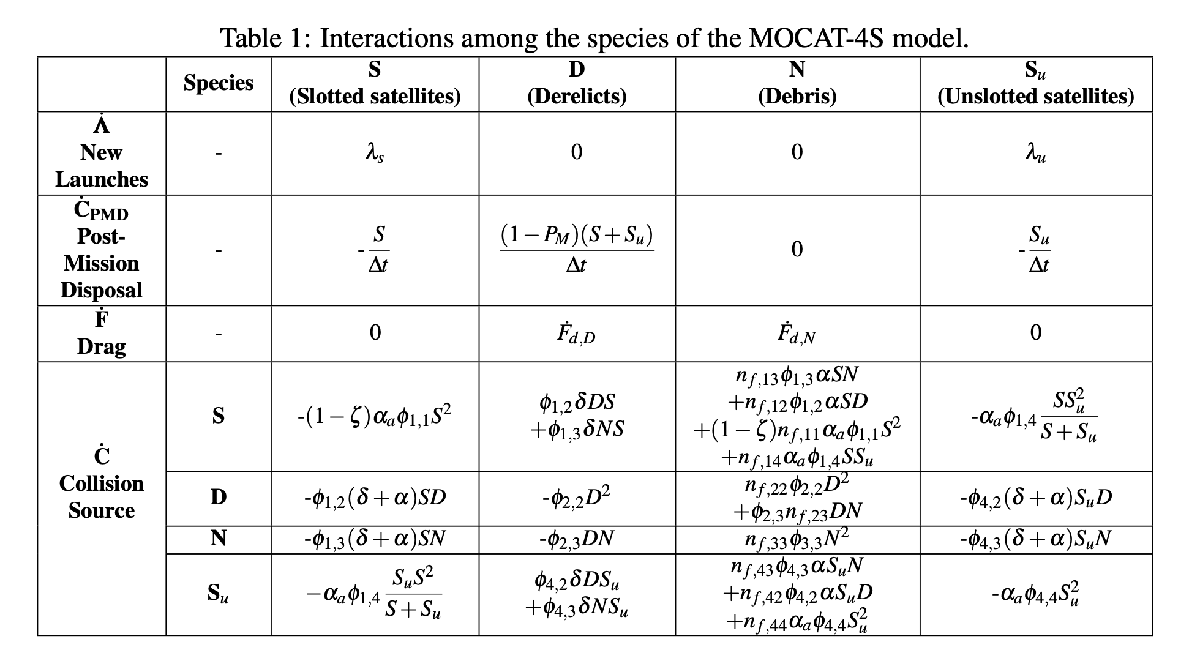

Species Names: S- Slotted Satellites, D- Derelict, N- Debris, Su- Unslotted Satellites

**Note: S in MOCAT-3 correspond to Su in MOCAT-4S. **

#### Parameter Definitions:

- $\lambda$: satellite launch rate

- $\alpha$: probability of unsuccessful collision avoidance between an active satellite and an inactive object

- $\alpha_a$: probability of unsuccessful collision avoidance between two active satellites. $\alpha_a$ <  $\alpha$

- $\phi_{XY}$: probability of collision between any species X and Y (i.e., S, D, and N), approximated from the kinetic theory of gases

- $\delta$: ratio of the density of disabling to lethal debris (this term considers the possibility that disabling collisions can generate new derelicts)

- $\zeta$: slotting effectiveness

- $P_M$: probability of success of post mission disposal

- $\Delta t$: time in which satellites are active before PMD

- $\dot{F_d}$: time derivative of species amount in a shell due to atmospheric drag

- $n_f$: number of debris fragments resulting from a collision between any species X and Y

- Set up paths and clear workspace to run file.

## **How to use it:**

This MATLAB Workbook is intended to be a straightforward, clear and interactive way to build familiarity with the MOCAT-SSEM model framework. The code is explained in comments in as much detail as possible for ease of use and clarity. **This workbook is intended to be a simple introduction and does not describe all functionality of the MOCAT-SSEM framework.**

Each model is built with a top-level simulation object. The simulation object has a scen_properties object, which sets global parameters, and a set of species with their own species_properties objects that define parameters for that species. The simulation object will automatically handle equation compilation and numerical integration of the model based on the provided parameters.

The recommended workflow beings with defining the scen_properties object and species before assembling and running the model.

To begin, you set the properties of the scenario you want to run such as the altitudes to be considered and atmospheric model to use, in **Define Scenario Properties**. Simply change the values that the variables are set to. 

As explained previously, MOCAT-4S considers 4 different species types, S, Su, D and N. You can set the properties of these species, such as the mass of derelict objects and launch rate of satellites in **Define Species Properties**. 

The sections **Collision Modeling **and **Define Initial population** require no user input but are necessary code. The first calculates the population gain/loss between species as they collide. The second, takes in the scenario properties you set earlier and a list of satellites from the file ('initialized.mat') and creates an array (x0) of of the number of species in each shell for the model at the start of the simulation.

You can select which, if any, visualizations of results you want to see in the final section, **Make and Run Simulation**. The plot for the evolution of total species numbers in each shell is already selected in my_sim.total_species_evol_vis();. To see the other visualizations, simply uncomment them (remove the % at the start of the line). You can also export numerical results for additional analysis as you desire.

Once you've finished all the inputs you'd like, simply run this workbook (F5) and it will begin. 

## Set up paths and clear workspace to run file.

This is necessary so that the model can find the necessary classes and functions. Clearing your workspace is not strictly necessary, but using an existing workspace may result in unintended interactions.

clear
clc

% The demo workbooks are in a subfolder of the main directory. We need to
% add the path recursively for the main directory.
fileName = matlab.desktop.editor.getActiveFilename;
[folder, ~, ~] = fileparts(fileName);
folder = fullfile(folder, '..');
addpath(fileparts(folder));
addpath(genpath(folder));
cd(folder);

## Define Scenario Properties

Set simulation parameters such as start time, duration, and time steps:

scenario_properties = MOCATSSEM_Scen_Prop_Cons( ...
    start_date = datetime(2022,1,30,9,42,28), ... # Starting date (year, month, day, hour, minute, second)
    simulation_duration = 100.0, ... % Years of simulation to run
    steps = 1000, ... % Number of steps to run in simulation
    min_altitude = 200, ... % Maximum altitude shell in km
    max_altitude = 900, ... % Minimum altitude shell in km
    shells = 5, ... % Number of altitude shells
    ... % We create this many equally spaced shells between the minimum and maximum altitudes
    delta = 10, ... %ratio of the density of disabling to lethal debris
    ... % this term, delta, considers the possibility that disabling collisions can generate new derelicts
    integrator = @ode15s); % MATLAB integrator used to run simulation
    % we typically use ode15s because often, models with many shells become stiff diff eqs.

You can choose between a static exponential or JB2008-based atmospheric density models. The static exponential model is not time dependent, and will run faster than JB2008. The JB2008 model is time/space-weather dependent and more accurate, but runs slower. You can see spikes in the JB2008 graph as the density changes over time. 

Set atmospheric density model:

atm_density_choice = "Static Exponential"

atm_density_choice = "Static Exponential"

switch atm_density_choice
    case "JB2008"
        scenario_properties.density_filepath = fullfile(".","Drag","Atmosphere Model", "JB2008", "Precomputed", "dens_highvar_2000.mat");
        scenario_properties.dens_model = @JB2008_dens_func;
        scenario_properties.time_dep_density = true;
    case "Static Exponential"
        scenario_properties.dens_model = @static_exp_dens_func;
        scenario_properties.time_dep_density = false;
end

Processes and saves the scenario properties you just set to be used in the simulation:

scen_properties = scen_properties_class(scenario_properties);

To access and edit ODE options, e.g.: 

- scen_properties.options.AbsTol = 1e-2;

- scen_properties.options.RelTol = 1e-2;

% scen_properties.options

## Define Species Properties

This is similiar to the MOCAT-3 model, but features an additional species S, which represents slotted satellites that are assumed to use orbits that are physically coordinated and thus subject to a further reduction in collision propbability. Define launch function: 

- Null: Launches no new satellites ever. May be helpful in debugging.

- Constant: Launches a constant number of satellites, with that number set by species_properties.lambda_constant in the Su species properties below.

Choose your launch function to determine the rate of new active satellites (species Su are inserted into orbit)

launch_func_choice = "Null"

launch_func_choice = "Null"

switch launch_func_choice
    case "Null"
        launch_func_sat = @launch_func_null;
    case "Constant"
        launch_func_sat = @launch_func_constant;
        lambda_constant = num2cell(500 * rand(scen_properties.N_shell,1));
end

 Define drag function:

my_drag_func = @drag_func;

**species_properties** is a struct object that takes in your inputs for the properties of a species. Once all the properties of a certain species have been set, they are saved and processed for the model by the species function. Then we clear species_properties at the end of each section so we can use it again for the next species (and we dont get properties left over from the last species).

species_properties = struct;

#### List of Species Properties

- *sym_name* - Symbolic name for species

- *Cd *- Coefficient of drag, unitless

- *mass* - Mass of species [kg]

- *radius *- Radius of species [m]

- *A *- Area of species in [m^2]

- *amr *- Area/mass ratio in [m^2/kg]

- *beta* - Ballistic coefficient

- *slotted *- Whether species is slotted or not [bool]

- *drag_effected* - Whether object decreases altitude due to drag or not [bool]

**Only for unslotted satellites (Su)**

- *lambda_constant - *Determines launch rate if launch function is Constant 

- *maneuverable *- Whether species is maneuverable or not [bool]

- *deltat* - Lifetime of spacecraft in years

- *Pm* - Post-mission disposal efficacy, if post-mission disposable is successful, the satellite is removed from the simulation. If it fails, the satellite transitions to a derelict [Float [0,1]]

- *alpha -* Efficacy of Collision Avoidance vs. inactive

- alpha_active = 0.01; % Efficacy of Collision Avoidance vs. other active 

- alpha = 2e-3; % Efficacy of Collision Avoidance vs. inactive

- *alpha_active* - Efficacy of Collision Avoidance vs. other active 

- *RBflag - *No Rocket Bodies yet.

**Only for slotted satellites (S)**

- *slotting_effectiveness - *proportion of conjunctions between pairs of slotted spacecraft that are mitigated by the slotting system

#### Define species properties for unslotted satellites

% Su
species_properties.sym_name = "Su";
species_properties.Cd = 2.2; % unitless
species_properties.mass = 223; % kg
species_properties.radius = 1.490/2; % m
species_properties.A = 1.741; % m^2
species_properties.amr = species_properties.A/species_properties.mass;  % m^2/kg
species_properties.amr = species_properties.A./species_properties.mass;  % m^2/kg
species_properties.beta = species_properties.Cd*species_properties.amr; % ballistic coefficient

% Orbit Properties
species_properties.slotted = false; % bool

% Capabilities
species_properties.drag_effected = false; % bool, does object decrease altitude due to drag
species_properties.active = true; % bool, use alpha_active for collisions vs. trackable
species_properties.maneuverable = true; % bool, use alpha_active for collisions vs. trackable
species_properties.trackable = true; % bool, others can avoid this with alpha.
species_properties.deltat = 5.0; % lifetime of spacecraft in years
species_properties.Pm = .90; % Post-mission disposal efficacy Float [0,1]
species_properties.alpha = 2e-3; % Efficacy of Collision Avoidance vs. inactive
species_properties.alpha_active = 1e-3; % Efficacy of Collision Avoidance vs. other active 
species_properties.RBflag = 0; % No Rocket Bodies yet.
if launch_func_choice == "Constant"
    species_properties.lambda_constant = lambda_constant; 
end

Create species instance with a launch function, post-mission disposable function, drag function, species properties which are specific to satellites, and scenario properties which are specific to the simulation. If post-mission disposable is successful (based on probabily Pm), the satellite is removed from the simulation. If it fails, the satellite transitions to a derelict.

Su_species = species(launch_func_sat, @pmd_func_sat, my_drag_func, species_properties, scen_properties);
species_properties = struct;

#### Define species properties for slotted satellites

% S
species_properties.sym_name = "S";
species_properties.Cd = 2.2; % unitless
species_properties.mass = 223; % kg
species_properties.radius = 1.490/2; % m
species_properties.A = 1.741; % m^2
species_properties.amr = species_properties.A/species_properties.mass;  % m^2/kg
species_properties.amr = species_properties.A./species_properties.mass;  % m^2/kg
species_properties.beta = species_properties.Cd*species_properties.amr; % ballistic coefficient

% Orbit Properties
species_properties.slotted = true; % bool
species_properties.slotting_effectiveness  = 1.0; % Float [0,1],

% Capabilities
species_properties.drag_effected = false; % bool, does object decrease altitude due to drag
species_properties.active = true; % bool, use alpha_active for collisions vs. trackable
species_properties.maneuverable = true; % bool, use alpha_active for collisions vs. trackable
species_properties.trackable = true; % bool, others can avoid this with alpha.
species_properties.deltat = 5.0; % lifetime of spacecraft in years
species_properties.Pm = .90; % Post-mission disposal efficacy Float [0,1]
species_properties.alpha = 2e-3; % Efficacy of Collision Avoidance vs. inactive
species_properties.alpha_active = 1e-3; % Efficacy of Collision Avoidance vs. other active 
species_properties.RBflag = 0; % No Rocket Bodies yet.
if launch_func_choice == "Constant"
    species_properties.lambda_constant = lambda_constant; 
end

S_species = species(launch_func_sat, @pmd_func_sat, my_drag_func, species_properties, scen_properties);
species_properties = struct;

#### Define species properties for derelict

% D
species_properties.sym_name = "D";
species_properties.Cd = Su_species.species_properties.Cd;
species_properties.mass = Su_species.species_properties.mass;
species_properties.radius = Su_species.species_properties.radius;
species_properties.A = Su_species.species_properties.A;
species_properties.amr = Su_species.species_properties.A/Su_species.species_properties.mass(1);  % m^2/kg
species_properties.beta = Su_species.species_properties.Cd*Su_species.species_properties.amr; % ballistic coefficient
species_properties.drag_effected = true; % bool, does object decrease altitude due to drag
species_properties.maneuverable = false; % bool, use alpha_active for collisions vs. trackable
species_properties.active = false;

D_species = species(@launch_func_null, @pmd_func_derelict, my_drag_func, species_properties, scen_properties);
D_species.species_properties.pmd_linked_species = [S_species, Su_species];
species_properties = struct;

#### Define species properties for debris.

% N
species_properties.sym_name = "N";
species_properties.Cd = 2.2; % unitless
species_properties.mass = 0.640; 
species_properties.radius = 0.180/2; % m
species_properties.A = 0.020;
species_properties.amr = species_properties.A/species_properties.mass;  % m^2/kg
species_properties.beta = species_properties.Cd*species_properties.amr; % ballistic coefficient
species_properties.drag_effected = true; % bool, does object decrease altitude due to drag
species_properties.maneuverable = false; % bool, use alpha_active for collisions vs. trackable
species_properties.active = false;

N_species = species(@launch_func_null, @pmd_func_none, my_drag_func, species_properties, scen_properties);
species_properties = struct;

Add all species to scenario properties.

scen_properties.species = [Su_species, S_species, D_species, N_species];
scen_properties.species_cell = struct('Su', Su_species, 'S', S_species,'D', D_species, 'N', N_species);

## Collision Modeling

Add/edit description and substitude code with function (TO DO)

%% Collision stuff
species_cross_pairs = nchoosek(scen_properties.species,2);

species_self_pairs = nchoosek(scen_properties.species,1);
species_self_pairs(:,2) = species_self_pairs(:,1);
species_pairs = vertcat(species_cross_pairs, species_self_pairs);

Create an empty array of class `species_pair_class`

species_pairs_classes = species_pair_class.empty;

Create array for fragments (used for n_f approach)

n_f = sym('n_f', [scen_properties.N_shell, 1]);

For each species pair:

- calculate and populate `gammas: `what is lost or gained from the species affected by the collision

- populate `source_sinks` : array of species affected by the collision

To account for an increase in debris:

- calculate populate `frags_made` with number of new fragments made per mass bin per collision velocity

- populate is_catastrophic with indicator of if collision was catastrophic per collision velocity

- update `gammas `for debris by adding the fragments from collisions

- add debris species `source_sinks` 

To account for changes in other species we calculate `gammas` based on the tables in the introduction.

Save collision information in `scen_properties.species_pairs`: an array of `species_pair_class `instances. These classes calculate `phi` and add the collision coefficients to the source sink equations.

numIterations = height(species_pairs);
disp("Creating species pairs...")

Creating species pairs...


% b = ProgressBar(numIterations,'Title', 'Progress');
for i = 1:height(species_pairs)
    i
    % b(1, [], []);
    n1 = species_pairs(i,1).species_properties.sym_name;
    n2 = species_pairs(i,2).species_properties.sym_name;
    s1 = species_pairs(i,1);
    s2 = species_pairs(i,2);

    gammas = sym.empty;
    source_sinks = species.empty;

    % populate gammas and source_sinks for collisions that affect the
    % number of unslotted satellites
    if n1 == "Su" || n2 == "Su"
        gammas = horzcat(gammas, ones([scen_properties.N_shell, 1], 'sym'));
        index = width(gammas);
        source_sinks(index) = Su_species;
        
        if s1.species_properties.maneuverable && s2.species_properties.maneuverable
            gammas(:,index) = -s1.species_properties.alpha_active;
            % if n1 == "S"
            %     gammas(:,index) = gammas(:,index) .* s2.species_properties.sym ./ (s1.species_properties.sym + s2.species_properties.sym);
            % elseif n2 == "S"
            %     gammas(:,index) = gammas(:,index) .* s1.species_properties.sym ./ (s1.species_properties.sym + s2.species_properties.sym);
            % end
        elseif n1 == "D" || n1 == "N" 
            gammas(:,index) = -(scen_properties.delta + s2.species_properties.alpha);
        elseif n2 == "D" || n2 == "N" 
            gammas(:,index) = -(scen_properties.delta + s1.species_properties.alpha);
        end
    end

    % populate gammas and source_sinks for collisions that affect the
    % number of unslotted satellites
    if n1 == "S" || n2 == "S"
        gammas = horzcat(gammas, ones([scen_properties.N_shell, 1], 'sym'));
        index = width(gammas);
        source_sinks(index) = S_species;
        
        if s1.species_properties.slotted && s2.species_properties.slotted
            gammas(:,index) = -s1.species_properties.alpha_active * (1-s1.species_properties.slotting_effectiveness);
        % elseif n1 == "Su"
        %     gammas(:,index) = -s1.species_properties.alpha_active * s2.species_properties.sym ./ (s1.species_properties.sym + s2.species_properties.sym);
        % elseif n2 == "Su"
        %     gammas(:,index) = -s2.species_properties.alpha_active * s1.species_properties.sym ./ (s1.species_properties.sym + s2.species_properties.sym);
        elseif n1 == "D" || n1 == "N" 
            gammas(:,index) = -(scen_properties.delta + s2.species_properties.alpha);
        elseif n2 == "D" || n2 == "N" 
            gammas(:,index) = -(scen_properties.delta + s1.species_properties.alpha);
        end
    end

    % populate gammas and source_sinks for collisions that affect the
    % number of derelict
    if (~s1.species_properties.maneuverable || ~s2.species_properties.maneuverable) && (n1 ~= "N" || n2 ~= "N")
        gammas = horzcat(gammas, ones([scen_properties.N_shell, 1], 'sym'));
        index = width(gammas);
        source_sinks(index) = D_species;
        if s1.species_properties.maneuverable
            gammas(:,index) = scen_properties.delta;
        elseif s2.species_properties.maneuverable
            gammas(:,index) = scen_properties.delta;
        else
            gammas(:,index) = -1;
        end
    end
    
    
    % Populate gammas and source_sinks for the debris species.
    index = width(gammas) + 1;
    gammas(:,index) = n_f;
    source_sinks(index) = N_species;

    if s1.species_properties.slotted && s2.species_properties.slotted
        gammas(:,index) = gammas(:,index) * s1.species_properties.alpha_active * (1-s1.species_properties.slotting_effectiveness);
    elseif s1.species_properties.maneuverable && s2.species_properties.maneuverable
        gammas(:,index) = gammas(:,index) * s1.species_properties.alpha_active;
    elseif s1.species_properties.maneuverable
        gammas(:,index) = gammas(:,index) * s1.species_properties.alpha;
    elseif s2.species_properties.maneuverable
        gammas(:,index) = gammas(:,index) * s2.species_properties.alpha;
    end

    % Make the class with the
    % equations.\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\\
    species_pairs_classes(i) = species_pair_class(s1, s2, gammas, source_sinks, scen_properties);

    % Correct equations such that collisions between satellites and
    % derelict are catastrophic instead of damaging
    if (n1 == "S" || n1 == "Su" || n1 == "D") && (n2 == "S" || n2 == "Su" || n2 == "D")
        M1 = s1.species_properties.mass;
        M2 = s2.species_properties.mass;
        n_f_catastrophic = 0.1*scen_properties.LC^(-1.71)*(M1+M2)^(0.75)* ones(size(scen_properties.v_imp2));
        n_f_damaging = 0.1*scen_properties.LC^(-1.71)*(min(M1,M2)*scen_properties.v_imp2.^2).^(0.75); 
        for testi = 1:length(scen_properties.species) % find debris equation index
            if scen_properties.species(testi).species_properties.sym_name == "N"
                eq_index_N = testi;
                break
            end
        end
        N_eqn = species_pairs_classes(i).eqs(:,eq_index_N);
        species_pairs_classes(i).eqs(:,eq_index_N) = N_eqn.*transpose(n_f_catastrophic)./transpose(n_f_damaging);
    end
    
    % To print out species_pairs_classes for debugging (uncomment following lines)
    species_pairs_classes(i)
    species_pairs_classes(i).nf
    species_pairs_classes(i).phi
    gammas
    T = vpa(species_pairs_classes(i).eqs,4)

end % End pairs loop

i = 1

ans =   species_pair_class with properties:

            name: "species_pair(Su,S)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 2.2201e-06
             phi: [2.8306e-08 2.7150e-08 2.6064e-08 2.5042e-08 2.4078e-08]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×3 sym]
    source_sinks: [1×3 species]
             eqs: [5×4 sym]


ans = 1.0e+03 *

    9.3590
    9.3590
    9.3590
    9.3590
    9.3590


ans = 1.0e-07 *

    0.2831    0.2715    0.2606    0.2504    0.2408


$$gammas = \left(\begin{array}{ccc} -\frac{1}{1000} & 1 & \frac{n_{\mathrm{f1}}}{1000}\\ -\frac{1}{1000} & 1 & \frac{n_{\mathrm{f2}}}{1000}\\ -\frac{1}{1000} & 1 & \frac{n_{\mathrm{f3}}}{1000}\\ -\frac{1}{1000} & 1 & \frac{n_{\mathrm{f4}}}{1000}\\ -\frac{1}{1000} & 1 & \frac{n_{\mathrm{f5}}}{1000} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} -2.831e-11\,S_{1}\,{\mathrm{Su}}_{1} & 2.831e-8\,S_{1}\,{\mathrm{Su}}_{1} & 0 & 1.409e-8\,S_{1}\,{\mathrm{Su}}_{1}\\ -2.715e-11\,S_{2}\,{\mathrm{Su}}_{2} & 2.715e-8\,S_{2}\,{\mathrm{Su}}_{2} & 0 & 1.351e-8\,S_{2}\,{\mathrm{Su}}_{2}\\ -2.606e-11\,S_{3}\,{\mathrm{Su}}_{3} & 2.606e-8\,S_{3}\,{\mathrm{Su}}_{3} & 0 & 1.297e-8\,S_{3}\,{\mathrm{Su}}_{3}\\ -2.504e-11\,S_{4}\,{\mathrm{Su}}_{4} & 2.504e-8\,S_{4}\,{\mathrm{Su}}_{4} & 0 & 1.246e-8\,S_{4}\,{\mathrm{Su}}_{4}\\ -2.408e-11\,S_{5}\,{\mathrm{Su}}_{5} & 2.408e-8\,S_{5}\,{\mathrm{Su}}_{5} & 0 & 1.198e-8\,S_{5}\,{\mathrm{Su}}_{5} \end{array}\right)$$

i = 2

ans =   species_pair_class with properties:

            name: "species_pair(Su,D)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 2.2201e-06
             phi: [2.8306e-08 2.7150e-08 2.6064e-08 2.5042e-08 2.4078e-08]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×3 sym]
    source_sinks: [1×3 species]
             eqs: [5×4 sym]


ans = 1.0e+03 *

    9.3590
    9.3590
    9.3590
    9.3590
    9.3590


ans = 1.0e-07 *

    0.2831    0.2715    0.2606    0.2504    0.2408


$$gammas = \left(\begin{array}{ccc} -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f1}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f2}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f3}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f4}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f5}}}{500} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} -2.831e-7\,D_{1}\,{\mathrm{Su}}_{1} & 0 & 2.831e-7\,D_{1}\,{\mathrm{Su}}_{1} & 2.818e-8\,D_{1}\,{\mathrm{Su}}_{1}\\ -2.716e-7\,D_{2}\,{\mathrm{Su}}_{2} & 0 & 2.715e-7\,D_{2}\,{\mathrm{Su}}_{2} & 2.703e-8\,D_{2}\,{\mathrm{Su}}_{2}\\ -2.607e-7\,D_{3}\,{\mathrm{Su}}_{3} & 0 & 2.606e-7\,D_{3}\,{\mathrm{Su}}_{3} & 2.595e-8\,D_{3}\,{\mathrm{Su}}_{3}\\ -2.505e-7\,D_{4}\,{\mathrm{Su}}_{4} & 0 & 2.504e-7\,D_{4}\,{\mathrm{Su}}_{4} & 2.493e-8\,D_{4}\,{\mathrm{Su}}_{4}\\ -2.408e-7\,D_{5}\,{\mathrm{Su}}_{5} & 0 & 2.408e-7\,D_{5}\,{\mathrm{Su}}_{5} & 2.397e-8\,D_{5}\,{\mathrm{Su}}_{5} \end{array}\right)$$

i = 3

ans =   species_pair_class with properties:

            name: "species_pair(Su,N)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 6.9723e-07
             phi: [8.8894e-09 8.5265e-09 8.1854e-09 7.8644e-09 7.5619e-09]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×3 sym]
    source_sinks: [1×3 species]
             eqs: [5×4 sym]


ans =   116.0473
  116.0473
  116.0473
  116.0473
  116.0473


ans = 1.0e-08 *

    0.8889    0.8527    0.8185    0.7864    0.7562


$$gammas = \left(\begin{array}{ccc} -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f1}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f2}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f3}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f4}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f5}}}{500} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} -8.891e-8\,N_{1}\,{\mathrm{Su}}_{1} & 0 & 8.889e-8\,N_{1}\,{\mathrm{Su}}_{1} & 2.063e-9\,N_{1}\,{\mathrm{Su}}_{1}\\ -8.528e-8\,N_{2}\,{\mathrm{Su}}_{2} & 0 & 8.527e-8\,N_{2}\,{\mathrm{Su}}_{2} & 1.979e-9\,N_{2}\,{\mathrm{Su}}_{2}\\ -8.187e-8\,N_{3}\,{\mathrm{Su}}_{3} & 0 & 8.185e-8\,N_{3}\,{\mathrm{Su}}_{3} & 1.9e-9\,N_{3}\,{\mathrm{Su}}_{3}\\ -7.866e-8\,N_{4}\,{\mathrm{Su}}_{4} & 0 & 7.864e-8\,N_{4}\,{\mathrm{Su}}_{4} & 1.825e-9\,N_{4}\,{\mathrm{Su}}_{4}\\ -7.563e-8\,N_{5}\,{\mathrm{Su}}_{5} & 0 & 7.562e-8\,N_{5}\,{\mathrm{Su}}_{5} & 1.755e-9\,N_{5}\,{\mathrm{Su}}_{5} \end{array}\right)$$

i = 4

ans =   species_pair_class with properties:

            name: "species_pair(S,D)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 2.2201e-06
             phi: [2.8306e-08 2.7150e-08 2.6064e-08 2.5042e-08 2.4078e-08]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×3 sym]
    source_sinks: [1×3 species]
             eqs: [5×4 sym]


ans = 1.0e+03 *

    9.3590
    9.3590
    9.3590
    9.3590
    9.3590


ans = 1.0e-07 *

    0.2831    0.2715    0.2606    0.2504    0.2408


$$gammas = \left(\begin{array}{ccc} -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f1}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f2}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f3}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f4}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f5}}}{500} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 0 & -2.831e-7\,D_{1}\,S_{1} & 2.831e-7\,D_{1}\,S_{1} & 2.818e-8\,D_{1}\,S_{1}\\ 0 & -2.716e-7\,D_{2}\,S_{2} & 2.715e-7\,D_{2}\,S_{2} & 2.703e-8\,D_{2}\,S_{2}\\ 0 & -2.607e-7\,D_{3}\,S_{3} & 2.606e-7\,D_{3}\,S_{3} & 2.595e-8\,D_{3}\,S_{3}\\ 0 & -2.505e-7\,D_{4}\,S_{4} & 2.504e-7\,D_{4}\,S_{4} & 2.493e-8\,D_{4}\,S_{4}\\ 0 & -2.408e-7\,D_{5}\,S_{5} & 2.408e-7\,D_{5}\,S_{5} & 2.397e-8\,D_{5}\,S_{5} \end{array}\right)$$

i = 5

ans =   species_pair_class with properties:

            name: "species_pair(S,N)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 6.9723e-07
             phi: [8.8894e-09 8.5265e-09 8.1854e-09 7.8644e-09 7.5619e-09]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×3 sym]
    source_sinks: [1×3 species]
             eqs: [5×4 sym]


ans =   116.0473
  116.0473
  116.0473
  116.0473
  116.0473


ans = 1.0e-08 *

    0.8889    0.8527    0.8185    0.7864    0.7562


$$gammas = \left(\begin{array}{ccc} -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f1}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f2}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f3}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f4}}}{500}\\ -\frac{5001}{500} & 10 & \frac{n_{\mathrm{f5}}}{500} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 0 & -8.891e-8\,N_{1}\,S_{1} & 8.889e-8\,N_{1}\,S_{1} & 2.063e-9\,N_{1}\,S_{1}\\ 0 & -8.528e-8\,N_{2}\,S_{2} & 8.527e-8\,N_{2}\,S_{2} & 1.979e-9\,N_{2}\,S_{2}\\ 0 & -8.187e-8\,N_{3}\,S_{3} & 8.185e-8\,N_{3}\,S_{3} & 1.9e-9\,N_{3}\,S_{3}\\ 0 & -7.866e-8\,N_{4}\,S_{4} & 7.864e-8\,N_{4}\,S_{4} & 1.825e-9\,N_{4}\,S_{4}\\ 0 & -7.563e-8\,N_{5}\,S_{5} & 7.562e-8\,N_{5}\,S_{5} & 1.755e-9\,N_{5}\,S_{5} \end{array}\right)$$

i = 6

ans =   species_pair_class with properties:

            name: "species_pair(D,N)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 6.9723e-07
             phi: [8.8894e-09 8.5265e-09 8.1854e-09 7.8644e-09 7.5619e-09]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×2 sym]
    source_sinks: [1×2 species]
             eqs: [5×4 sym]


ans =   116.0473
  116.0473
  116.0473
  116.0473
  116.0473


ans = 1.0e-08 *

    0.8889    0.8527    0.8185    0.7864    0.7562


$$gammas = \left(\begin{array}{cc} -1 & n_{\mathrm{f1}}\\ -1 & n_{\mathrm{f2}}\\ -1 & n_{\mathrm{f3}}\\ -1 & n_{\mathrm{f4}}\\ -1 & n_{\mathrm{f5}} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 0 & 0 & -8.889e-9\,D_{1}\,N_{1} & 1.032e-6\,D_{1}\,N_{1}\\ 0 & 0 & -8.527e-9\,D_{2}\,N_{2} & 9.895e-7\,D_{2}\,N_{2}\\ 0 & 0 & -8.185e-9\,D_{3}\,N_{3} & 9.499e-7\,D_{3}\,N_{3}\\ 0 & 0 & -7.864e-9\,D_{4}\,N_{4} & 9.126e-7\,D_{4}\,N_{4}\\ 0 & 0 & -7.562e-9\,D_{5}\,N_{5} & 8.775e-7\,D_{5}\,N_{5} \end{array}\right)$$

i = 7

ans =   species_pair_class with properties:

            name: "species_pair(Su,Su)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 2.2201e-06
             phi: [2.8306e-08 2.7150e-08 2.6064e-08 2.5042e-08 2.4078e-08]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×2 sym]
    source_sinks: [1×2 species]
             eqs: [5×4 sym]


ans = 1.0e+03 *

    9.3590
    9.3590
    9.3590
    9.3590
    9.3590


ans = 1.0e-07 *

    0.2831    0.2715    0.2606    0.2504    0.2408


$$gammas = \left(\begin{array}{cc} -\frac{1}{1000} & \frac{n_{\mathrm{f1}}}{1000}\\ -\frac{1}{1000} & \frac{n_{\mathrm{f2}}}{1000}\\ -\frac{1}{1000} & \frac{n_{\mathrm{f3}}}{1000}\\ -\frac{1}{1000} & \frac{n_{\mathrm{f4}}}{1000}\\ -\frac{1}{1000} & \frac{n_{\mathrm{f5}}}{1000} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} -2.831e-11\,{{\mathrm{Su}}_{1}}^{2} & 0 & 0 & 1.409e-8\,{{\mathrm{Su}}_{1}}^{2}\\ -2.715e-11\,{{\mathrm{Su}}_{2}}^{2} & 0 & 0 & 1.351e-8\,{{\mathrm{Su}}_{2}}^{2}\\ -2.606e-11\,{{\mathrm{Su}}_{3}}^{2} & 0 & 0 & 1.297e-8\,{{\mathrm{Su}}_{3}}^{2}\\ -2.504e-11\,{{\mathrm{Su}}_{4}}^{2} & 0 & 0 & 1.246e-8\,{{\mathrm{Su}}_{4}}^{2}\\ -2.408e-11\,{{\mathrm{Su}}_{5}}^{2} & 0 & 0 & 1.198e-8\,{{\mathrm{Su}}_{5}}^{2} \end{array}\right)$$

i = 8

ans =   species_pair_class with properties:

            name: "species_pair(S,S)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 2.2201e-06
             phi: [2.8306e-08 2.7150e-08 2.6064e-08 2.5042e-08 2.4078e-08]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×2 sym]
    source_sinks: [1×2 species]
             eqs: [5×4 sym]


ans = 1.0e+03 *

    9.3590
    9.3590
    9.3590
    9.3590
    9.3590


ans = 1.0e-07 *

    0.2831    0.2715    0.2606    0.2504    0.2408


$$gammas = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

i = 9

ans =   species_pair_class with properties:

            name: "species_pair(D,D)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 2.2201e-06
             phi: [2.8306e-08 2.7150e-08 2.6064e-08 2.5042e-08 2.4078e-08]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×2 sym]
    source_sinks: [1×2 species]
             eqs: [5×4 sym]


ans = 1.0e+03 *

    9.3590
    9.3590
    9.3590
    9.3590
    9.3590


ans = 1.0e-07 *

    0.2831    0.2715    0.2606    0.2504    0.2408


$$gammas = \left(\begin{array}{cc} -1 & n_{\mathrm{f1}}\\ -1 & n_{\mathrm{f2}}\\ -1 & n_{\mathrm{f3}}\\ -1 & n_{\mathrm{f4}}\\ -1 & n_{\mathrm{f5}} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 0 & 0 & -2.831e-8\,{D_{1}}^{2} & 1.409e-5\,{D_{1}}^{2}\\ 0 & 0 & -2.715e-8\,{D_{2}}^{2} & 1.351e-5\,{D_{2}}^{2}\\ 0 & 0 & -2.606e-8\,{D_{3}}^{2} & 1.297e-5\,{D_{3}}^{2}\\ 0 & 0 & -2.504e-8\,{D_{4}}^{2} & 1.246e-5\,{D_{4}}^{2}\\ 0 & 0 & -2.408e-8\,{D_{5}}^{2} & 1.198e-5\,{D_{5}}^{2} \end{array}\right)$$

i = 10

ans =   species_pair_class with properties:

            name: "species_pair(N,N)"
        species1: [1×1 species]
        species2: [1×1 species]
           sigma: 3.2400e-08
             phi: [4.1309e-10 3.9623e-10 3.8038e-10 3.6546e-10 3.5140e-10]
    catastrophic: [0 0 0 0 0]
              nf: [5×1 double]
           delta: []
          gammas: [5×1 sym]
    source_sinks: [1×1 species]
             eqs: [5×4 sym]


ans =   116.0473
  116.0473
  116.0473
  116.0473
  116.0473


ans = 1.0e-09 *

    0.4131    0.3962    0.3804    0.3655    0.3514


$$gammas = \left(\begin{array}{c} n_{\mathrm{f1}}\\ n_{\mathrm{f2}}\\ n_{\mathrm{f3}}\\ n_{\mathrm{f4}}\\ n_{\mathrm{f5}} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 0 & 0 & 0 & 4.794e-8\,{N_{1}}^{2}\\ 0 & 0 & 0 & 4.598e-8\,{N_{2}}^{2}\\ 0 & 0 & 0 & 4.414e-8\,{N_{3}}^{2}\\ 0 & 0 & 0 & 4.241e-8\,{N_{4}}^{2}\\ 0 & 0 & 0 & 4.078e-8\,{N_{5}}^{2} \end{array}\right)$$

% b.release();
scen_properties.species_pairs = species_pairs_classes;
disp("Done")

Done


## Define Initial Population

This section creates an initial population for satellites, derelict and debris. The `MC2SSEM_population` function takes a list of space objects from `initialized.mat` and categorizes them into satellites, derelict and debris. x0 is a total count of each species in each shell that we will start the simulation from.

Species order and definition (NOTE: do not change the order): 

- S = Active slotted satellites

- D = Derelict objects

- N = Debris objects

- Su = Active unslotted satellites

- B = Rocket bodies

- U = Lethal non-trackable debris objects (AKA N with trackable = False)

scen_properties.species_types = [isfield(scen_properties.species_cell,'S') && ~isempty(scen_properties.species_cell.S),...
                                 isfield(scen_properties.species_cell,'D') && ~isempty(scen_properties.species_cell.D),...
                                 isfield(scen_properties.species_cell,'N') && ~isempty(scen_properties.species_cell.N),...
                                 isfield(scen_properties.species_cell,'Su') && ~isempty(scen_properties.species_cell.Su),...
                                 isfield(scen_properties.species_cell,'B') && ~isempty(scen_properties.species_cell.B),...
                                 isfield(scen_properties.species_cell,'U') && ~isempty(scen_properties.species_cell.U)];
load('initialized.mat', 'sats');
x0 = MC2SSEM_population(sats,scen_properties);

% Display starting population
for spec_index = 1:length(scen_properties.species)
   spec_names(spec_index) = scen_properties.species(spec_index).species_properties.sym_name;
end

T = array2table(x0, 'VariableNames', spec_names);
disp(array2table([[1:scen_properties.N_shell]',x0], 'VariableNames', ['Shell', spec_names]))

    Shell     Su      S       D      N  
    _____    ____    ____    ___    ____

      1        17      10     19      62
      2       373      54    204     443
      3      1232    2439    295     699
      4       233      27    382    1758
      5         0       0      0       0



## Build Model

`simulation_class` is responsible for building and running the model. The `build_model()` function compiles the equations. It adds together all of the terms (regarding launch, collisions, post-mission disposal, and atmospheric drag).

Building the model is only required once in order to run the model if the user doesn't want to change any input parameters.

x0 = reshape(table2array(T), [], 1);% Pad initial conditions with the indicator variables
my_sim = simulation_class(scen_properties.species, scen_properties);
my_sim.build_model();

Building model...


ans =   simulation_class with properties:

       species_list: [1×4 species]
    scen_properties: [1×1 scen_properties_class]
          equations: [5×4 sym]
            results: []
           xdot_eqs: []
           xdot_fun: []
            var_col: []
    drag_term_upper: []
      drag_term_cur: []


Now processing Su
Now processing S
Now processing D
Now processing N
Done building model.


## Run Simulation

`run_model()` is where the simulation model is actually run. It takes a list of initial conditions (x0).

The function also accepts many optional parameters: 

- progressBar - Displays percentage of simulation run in another window - bool 

- disp_times - Displays time steps in console - bool

- start_date - Start date of simulation - MATLAB datetime object

- simulation_duration - Years of simulation to run - double

- N_step - Number of simulations steps to run - int

x0 = reshape(x0, [], 1);
my_sim.run_model(x0, 'progressBar', true, 'disp_times', false) 

## Plots

Produces a Figure with subplots for each species population evolution over time 

Producing visuals for the evolution of each species.


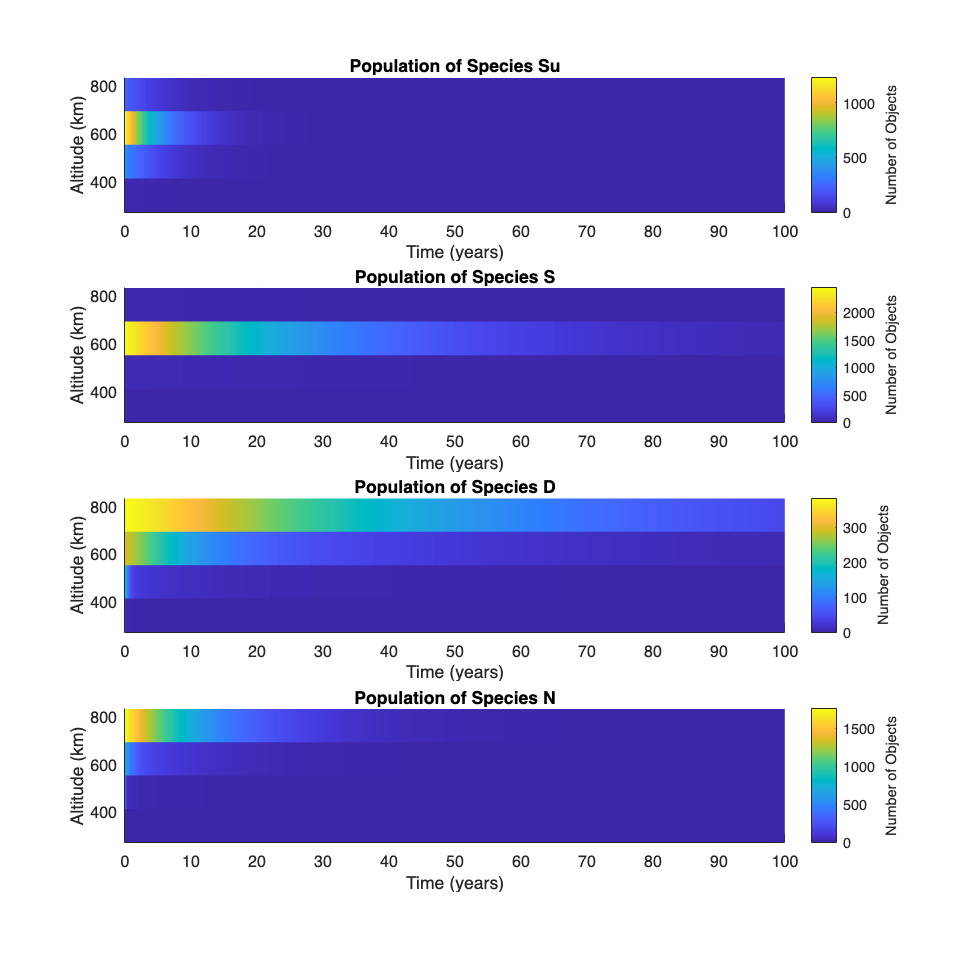

my_sim.total_species_evol_vis();

verify_equations(my_sim)

Su


$$ans = \left(\begin{array}{c} -0.2\,{\mathrm{Su}}_{1}-8.891e-8\,N_{1}\,{\mathrm{Su}}_{1}-2.831e-11\,S_{1}\,{\mathrm{Su}}_{1}-2.831e-11\,{{\mathrm{Su}}_{1}}^{2}-2.831e-7\,D_{1}\,{\mathrm{Su}}_{1}\\ -0.2\,{\mathrm{Su}}_{2}-8.528e-8\,N_{2}\,{\mathrm{Su}}_{2}-2.715e-11\,S_{2}\,{\mathrm{Su}}_{2}-2.715e-11\,{{\mathrm{Su}}_{2}}^{2}-2.716e-7\,D_{2}\,{\mathrm{Su}}_{2}\\ -0.2\,{\mathrm{Su}}_{3}-8.187e-8\,N_{3}\,{\mathrm{Su}}_{3}-2.606e-11\,S_{3}\,{\mathrm{Su}}_{3}-2.606e-11\,{{\mathrm{Su}}_{3}}^{2}-2.607e-7\,D_{3}\,{\mathrm{Su}}_{3}\\ -0.2\,{\mathrm{Su}}_{4}-7.866e-8\,N_{4}\,{\mathrm{Su}}_{4}-2.504e-11\,S_{4}\,{\mathrm{Su}}_{4}-2.504e-11\,{{\mathrm{Su}}_{4}}^{2}-2.505e-7\,D_{4}\,{\mathrm{Su}}_{4}\\ -0.2\,{\mathrm{Su}}_{5}-7.563e-8\,N_{5}\,{\mathrm{Su}}_{5}-2.408e-11\,S_{5}\,{\mathrm{Su}}_{5}-2.408e-11\,{{\mathrm{Su}}_{5}}^{2}-2.408e-7\,D_{5}\,{\mathrm{Su}}_{5} \end{array}\right)$$

lam_Su1 - 0.2*Su1 - 8.891e-8*N1*Su1 - 2.831e-11*Su1^2 - 2.831e-7*D1*Su1 - (2.831e-11*S1*Su1^2)/(S1 + Su1)
lam_Su2 - 0.2*Su2 - 8.528e-8*N2*Su2 - 2.715e-11*Su2^2 - 2.716e-7*D2*Su2 - (2.715e-11*S2*Su2^2)/(S2 + Su2)
lam_Su3 - 0.2*Su3 - 8.187e-8*N3*Su3 - 2.606e-11*Su3^2 - 2.607e-7*D3*Su3 - (2.606e-11*S3*Su3^2)/(S3 + Su3)
lam_Su4 - 0.2*Su4 - 7.866e-8*N4*Su4 - 2.504e-11*Su4^2 - 2.505e-7*D4*Su4 - (2.504e-11*S4*Su4^2)/(S4 + Su4)
lam_Su5 - 0.2*Su5 - 7.563e-8*N5*Su5 - 2.408e-11*Su5^2 - 2.408e-7*D5*Su5 - (2.408e-11*S5*Su5^2)/(S5 + Su5)
S


$$ans = \left(\begin{array}{c} 2.831e-8\,S_{1}\,{\mathrm{Su}}_{1}-8.891e-8\,N_{1}\,S_{1}-0.2\,S_{1}-2.831e-7\,D_{1}\,S_{1}\\ 2.715e-8\,S_{2}\,{\mathrm{Su}}_{2}-8.528e-8\,N_{2}\,S_{2}-0.2\,S_{2}-2.716e-7\,D_{2}\,S_{2}\\ 2.606e-8\,S_{3}\,{\mathrm{Su}}_{3}-8.187e-8\,N_{3}\,S_{3}-0.2\,S_{3}-2.607e-7\,D_{3}\,S_{3}\\ 2.504e-8\,S_{4}\,{\mathrm{Su}}_{4}-7.866e-8\,N_{4}\,S_{4}-0.2\,S_{4}-2.505e-7\,D_{4}\,S_{4}\\ 2.408e-8\,S_{5}\,{\mathrm{Su}}_{5}-7.563e-8\,N_{5}\,S_{5}-0.2\,S_{5}-2.408e-7\,D_{5}\,S_{5} \end{array}\right)$$

lam_S1 - 0.2*S1 - 8.891e-8*N1*S1 - 2.831e-7*D1*S1 - (2.831e-11*S1^2*Su1)/(S1 + Su1)
lam_S2 - 0.2*S2 - 8.528e-8*N2*S2 - 2.716e-7*D2*S2 - (2.715e-11*S2^2*Su2)/(S2 + Su2)
lam_S3 - 0.2*S3 - 8.187e-8*N3*S3 - 2.607e-7*D3*S3 - (2.606e-11*S3^2*Su3)/(S3 + Su3)
lam_S4 - 0.2*S4 - 7.866e-8*N4*S4 - 2.505e-7*D4*S4 - (2.504e-11*S4^2*Su4)/(S4 + Su4)
lam_S5 - 0.2*S5 - 7.563e-8*N5*S5 - 2.408e-7*D5*S5 - (2.408e-11*S5^2*Su5)/(S5 + Su5)
D


$$ans = \left(\begin{array}{c} 2.298\,D_{2}-55.29\,D_{1}+0.02\,S_{1}+0.02\,{\mathrm{Su}}_{1}+8.889e-8\,N_{1}\,S_{1}+8.889e-8\,N_{1}\,{\mathrm{Su}}_{1}-2.831e-8\,{D_{1}}^{2}-8.889e-9\,D_{1}\,N_{1}+2.831e-7\,D_{1}\,S_{1}+2.831e-7\,D_{1}\,{\mathrm{Su}}_{1}\\ 0.1959\,D_{3}-2.298\,D_{2}+0.02\,S_{2}+0.02\,{\mathrm{Su}}_{2}+8.527e-8\,N_{2}\,S_{2}+8.527e-8\,N_{2}\,{\mathrm{Su}}_{2}-2.715e-8\,{D_{2}}^{2}-8.527e-9\,D_{2}\,N_{2}+2.715e-7\,D_{2}\,S_{2}+2.715e-7\,D_{2}\,{\mathrm{Su}}_{2}\\ 0.02251\,D_{4}-0.1959\,D_{3}+0.02\,S_{3}+0.02\,{\mathrm{Su}}_{3}+8.185e-8\,N_{3}\,S_{3}+8.185e-8\,N_{3}\,{\mathrm{Su}}_{3}-2.606e-8\,{D_{3}}^{2}-8.185e-9\,D_{3}\,N_{3}+2.606e-7\,D_{3}\,S_{3}+2.606e-7\,D_{3}\,{\mathrm{Su}}_{3}\\ 0.003794\,D_{5}-0.02251\,D_{4}+0.02\,S_{4}+0.02\,{\mathrm{Su}}_{4}+7.864e-8\,N_{4}\,S_{4}+7.864e-8\,N_{4}\,{\mathrm{Su}}_{4}-2.504e-8\,{D_{4}}^{2}-7.864e-9\,D_{4}\,N_{4}+2.504e-7\,D_{4}\,S_{4}+2.504e-7\,D_{4}\,{\mathrm{Su}}_{4}\\ 0.02\,S_{5}-0.003794\,D_{5}+0.02\,{\mathrm{Su}}_{5}+7.562e-8\,N_{5}\,S_{5}+7.562e-8\,N_{5}\,{\mathrm{Su}}_{5}-2.408e-8\,{D_{5}}^{2}-7.562e-9\,D_{5}\,N_{5}+2.408e-7\,D_{5}\,S_{5}+2.408e-7\,D_{5}\,{\mathrm{Su}}_{5} \end{array}\right)$$

2.298*D2 - 55.29*D1 + 0.02*S1 + 0.02*Su1 + 8.889e-8*N1*S1 + 8.889e-8*N1*Su1 - 2.831e-8*D1^2 - 8.889e-9*D1*N1 + 2.831e-7*D1*S1 + 2.831e-7*D1*Su1
0.1959*D3 - 2.298*D2 + 0.02*S2 + 0.02*Su2 + 8.527e-8*N2*S2 + 8.527e-8*N2*Su2 - 2.715e-8*D2^2 - 8.527e-9*D2*N2 + 2.715e-7*D2*S2 + 2.715e-7*D2*Su2
0.02251*D4 - 0.1959*D3 + 0.02*S3 + 0.02*Su3 + 8.185e-8*N3*S3 + 8.185e-8*N3*Su3 - 2.606e-8*D3^2 - 8.185e-9*D3*N3 + 2.606e-7*D3*S3 + 2.606e-7*D3*Su3
0.003794*D5 - 0.02251*D4 + 0.02*S4 + 0.02*Su4 + 7.864e-8*N4*S4 + 7.864e-8*N4*Su4 - 2.504e-8*D4^2 - 7.864e-9*D4*N4 + 2.504e-7*D4*S4 + 2.504e-7*D4*Su4
0.02*S5 - 0.003794*D5 + 0.02*Su5 + 7.562e-8*N5*S5 + 7.562e-8*N5*Su5 - 2.408e-8*D5^2 - 7.562e-9*D5*N5 + 2.408e-7*D5*S5 + 2.408e-7*D5*Su5
N


$$ans = \left(\begin{array}{c} 9.197\,N_{2}-221.3\,N_{1}+2.063e-9\,N_{1}\,S_{1}+2.063e-9\,N_{1}\,{\mathrm{Su}}_{1}+1.409e-8\,S_{1}\,{\mathrm{Su}}_{1}+1.409e-5\,{D_{1}}^{2}+4.794e-8\,{N_{1}}^{2}+1.409e-8\,{{\mathrm{Su}}_{1}}^{2}+1.032e-6\,D_{1}\,N_{1}+2.818e-8\,D_{1}\,S_{1}+2.818e-8\,D_{1}\,{\mathrm{Su}}_{1}\\ 0.7843\,N_{3}-9.197\,N_{2}+1.979e-9\,N_{2}\,S_{2}+1.979e-9\,N_{2}\,{\mathrm{Su}}_{2}+1.351e-8\,S_{2}\,{\mathrm{Su}}_{2}+1.351e-5\,{D_{2}}^{2}+4.598e-8\,{N_{2}}^{2}+1.351e-8\,{{\mathrm{Su}}_{2}}^{2}+9.895e-7\,D_{2}\,N_{2}+2.703e-8\,D_{2}\,S_{2}+2.703e-8\,D_{2}\,{\mathrm{Su}}_{2}\\ 0.09009\,N_{4}-0.7843\,N_{3}+1.9e-9\,N_{3}\,S_{3}+1.9e-9\,N_{3}\,{\mathrm{Su}}_{3}+1.297e-8\,S_{3}\,{\mathrm{Su}}_{3}+1.297e-5\,{D_{3}}^{2}+4.414e-8\,{N_{3}}^{2}+1.297e-8\,{{\mathrm{Su}}_{3}}^{2}+9.499e-7\,D_{3}\,N_{3}+2.595e-8\,D_{3}\,S_{3}+2.595e-8\,D_{3}\,{\mathrm{Su}}_{3}\\ 0.01519\,N_{5}-0.09009\,N_{4}+1.825e-9\,N_{4}\,S_{4}+1.825e-9\,N_{4}\,{\mathrm{Su}}_{4}+1.246e-8\,S_{4}\,{\mathrm{Su}}_{4}+1.246e-5\,{D_{4}}^{2}+4.241e-8\,{N_{4}}^{2}+1.246e-8\,{{\mathrm{Su}}_{4}}^{2}+9.126e-7\,D_{4}\,N_{4}+2.493e-8\,D_{4}\,S_{4}+2.493e-8\,D_{4}\,{\mathrm{Su}}_{4}\\ 1.755e-9\,N_{5}\,S_{5}-0.01519\,N_{5}+1.755e-9\,N_{5}\,{\mathrm{Su}}_{5}+1.198e-8\,S_{5}\,{\mathrm{Su}}_{5}+1.198e-5\,{D_{5}}^{2}+4.078e-8\,{N_{5}}^{2}+1.198e-8\,{{\mathrm{Su}}_{5}}^{2}+8.775e-7\,D_{5}\,N_{5}+2.397e-8\,D_{5}\,S_{5}+2.397e-8\,D_{5}\,{\mathrm{Su}}_{5} \end{array}\right)$$

9.197*N2 - 221.3*N1 + 2.063e-9*N1*S1 + 2.063e-9*N1*Su1 + 1.409e-8*S1*Su1 + 1.409e-5*D1^2 + 4.794e-8*N1^2 + 1.409e-8*Su1^2 + 1.032e-6*D1*N1 + 2.818e-8*D1*S1 + 2.818e-8*D1*Su1
0.7843*N3 - 9.197*N2 + 1.979e-9*N2*S2 + 1.979e-9*N2*Su2 + 1.351e-8*S2*Su2 + 1.351e-5*D2^2 + 4.598e-8*N2^2 + 1.351e-8*Su2^2 + 9.895e-7*D2*N2 + 2.703e-8*D2*S2 + 2.703e-8*D2*Su2
0.09009*N4 - 0.7843*N3 + 1.9e-9*N3*S3 + 1.9e-9*N3*Su3 + 1.297e-8*S3*Su3 + 1.297e-5*D3^2 + 4.414e-8*N3^2 + 1.297e-8*Su3^2 + 9.499e-7*D3*N3 + 2.595e-8*D3*S3 + 2.595e-8*D3*Su3
0.01519*N5 - 0.09009*N4 + 1.825e-9*N4*S4 + 1.825e-9*N4*Su4 + 1.246e-8*S4*Su4 + 1.246e-5*D4^2 + 4.241e-8*N4^2 + 1.246e-8*Su4^2 + 9.126e-7*D4*N4 + 2.493e-8*D4*S4 + 2.493e-8*D4*Su4
1.755e-9*N5*S5 - 0.01519*N5 + 1.755e-9*N5*Su5 + 1.198e-8*S5*Su5 + 1.198e-5*D5^2 + 4.078e-8*N5^2 + 1.198e-8*Su5^2 + 8.775e-7*D5*N5 + 2.397e-8*D5*S5 + 2.397e-8*D5*Su5


Produces a Figure with subplots for each species population density evolution over time 

Producing visuals for the evolution of each species' density.


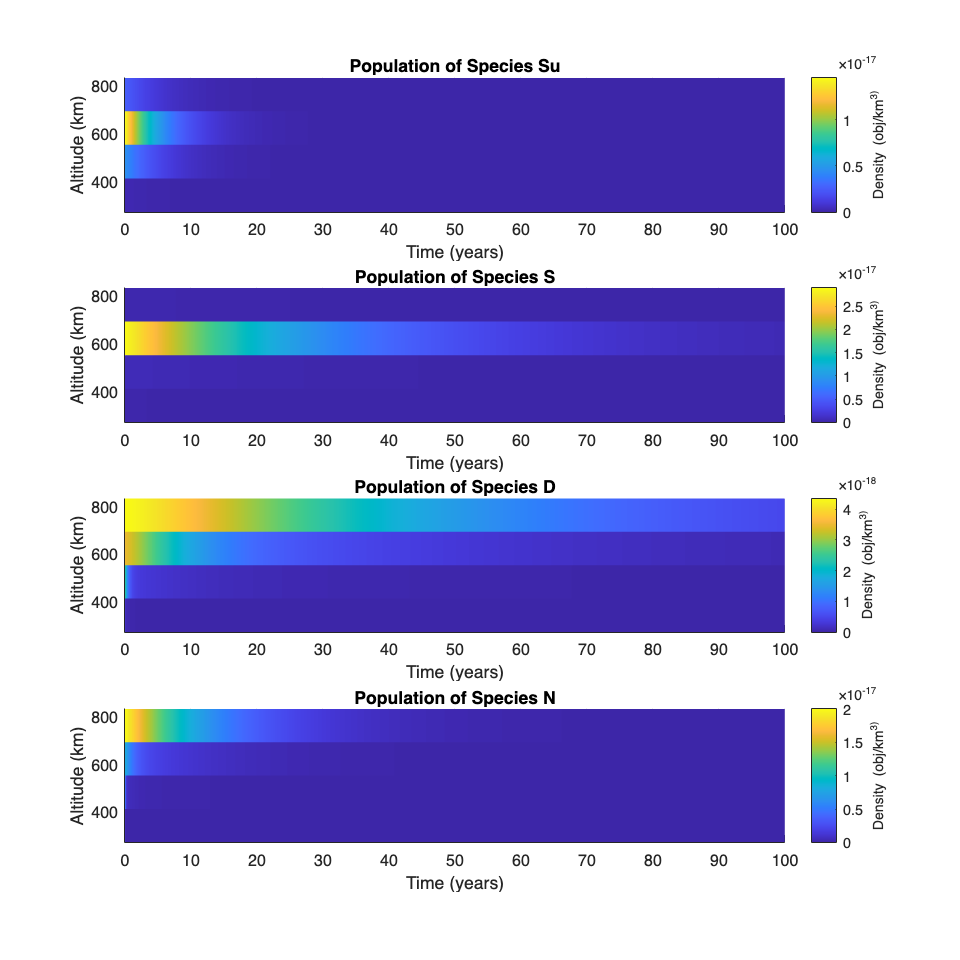

my_sim.density_species_evol_vis();

Produces a Figure for the evolution of the total population of each species over time across all shells 

% my_sim.pop_vs_time_vis();

Graphs the rate of change for the total inactive population added across all altitudes at each time. 

percentage = (bool, defaults to false) that expresses rate of change in percentage terms. 

% my_sim.total_deb_pop_time_deriv('percentage', true) 

Produces a Figure with subplots for numerical derivative of each inactive species population evolution over time constraint is the value used in the color scale.

percentage is bool (default false) for whether to use percentage or absolute.

color_scale_crop_percentiles is pair (default [0, 100]). Color scale will be  set based on the inclusive range from the lower value to the higher value.

% my_sim.total_deb_species_deriv_evolv_vis();

Produces a Figure for the evolution of the total population of all objects over time across all shells 

% my_sim.tot_vs_time_vis();

Produces a Figure per species for the evolution of the total population of each species over time across all shells 

% my_sim.species_time_vis();

Displays total spatial density in each shell over time 

% my_sim.density_vs_time();

Computes and displays Number_Time_Product

% my_sim.num_time_prod(x0);

Produces a Figure comparing the total initial number of objects and the total final number of objects 

% my_sim.init_vs_final_vis();

Produces a Figure comparing the initial population of each species alongside a plot of the final population of each species 

% my_sim.init_and_final_vis();

Produces a Figure showing number of debris across altitudes by debris type 

% my_sim.final_debris_vis();

Computes and displays cumulative Criticality of Space Index - CSI

% my_sim.cum_CSI()

Close all figures created (or run this line in your command line)

% close all